clc;
clear all;
close all;

## Setup

## Assign Variables

Here are stored all the variables for parameters and settings in the whole code

%% Matrix of dependencies (1 in forward direction, -1 in backwards direction, else 0)
matrix_of_dependencies=[0 1 0; -1 0 1; 0 -1 0]
%% Physical constants

%% Simulation variables
%initial_condition = %initial angles for oscillation of double pendulum

## Calibration Routine %all the steps should be put in one function [offsets_vector]=calibrate_sensors()

Calculate drifts and position and orientation offsets

## Initialize the buffer

Opens file.JSON to be used for sending information to UNITY

%% open file.JSON

## Simulation

Simulation of a double pendulum motion with viscous damping using ODE45 or RKF45 method 

Syntax: pendulum simulation(time, initial_condition)

[t,P1x_simulation,P1z_simulation]=pendulum_simulation(time,pi/7);

## Main Program %a while loop stopping on keyboard interrupt

Reads data, performs optimization, calculates position, adjusts frame rate for UNITY, writes position estimates to recording.JSON and plots motion in real time

%% a while loop reacting to keyboard interrupt



placement of sensors from top to bottom

IMU 1 on I2C channel ..

|

IMU 2 on I2C channel  ..

|

IMU 3 on I2C channel .. 

## Read New Data %has to be changed to update at every timestep

SETUP INFORMATION:

orientation of the senstor in rest state = [x-up, z-out of page (CCW), y-right]

%% Here is the data from the buffer from ESP32
%data = csvread('2_sensor_data.txt',2,0);
%% for loop for assigning accelerations, angular velocities and magnetometer data for all sensors

%% angular velocities
%% make angular velocity data homogenous

%% accelerations
%% make acceleration data homogeneous

%% magnetometer data
%% make magnetometer data homogenous

## Calculate New Position %has to be changed to update every timestep + write to JSON file

Pendulum motion from sensor 1 data:

%% Position estimate of the dependent sensor #1 down the line assuming rigid body (by extrapolating the feeding sensor #-1 data) 
%%this should be written as a function to calculate position of the next sensor down the line (dependent sensor)
%[position_matrix]=position_next(matrix_of_dependencies)

## Optimization

Optimization procedure utilizing probability density functions for position estimation

%%N = length(time);    % N = number of data samples

## Write to .JSON or CSV buffer %has to be changed to update every timestep + delete old readings

Writing to recording.JSON file a

%data_position=[time position_matrix]; %put together matrix with all vectors as columns
%write_to_JSON(data_position); 

Writing to a comma separated file

%write_to_txt(data_position);

## Update the plot %has to be changed so it plots position in real time

Shows the motion of the setup in real time

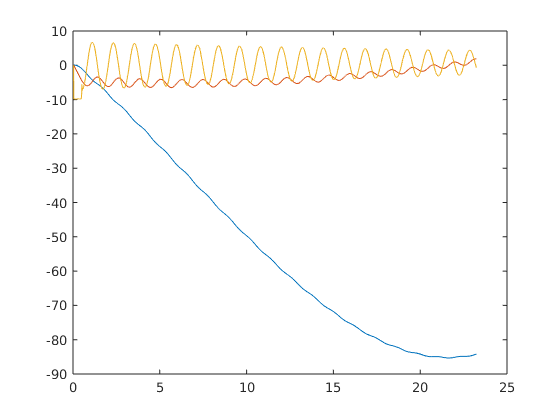

P2_Z_offset = P1fromP2(1,start_offset:end);

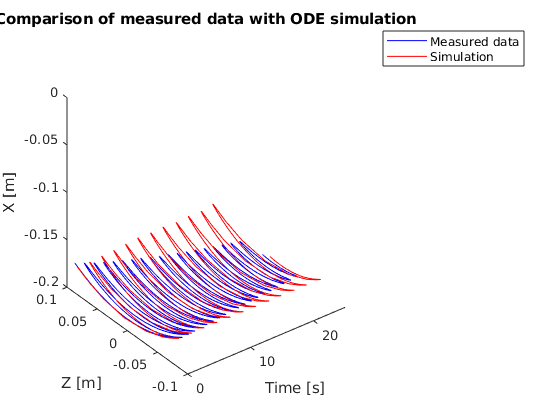

P2_X_offset = P1fromP2(2,start_offset:end);
figure(1);
plot3(time_offset,P2_Z_offset,P2_X_offset,'b');
hold on
plot3(t,P1x_simulation,P1z_simulation,'r');
axis([0 25 -0.1 0.1 -0.2 0]);
title("Comparison of measured data with ODE simulation")
xlabel("Time [s]")
ylabel("Z [m]")
zlabel("X [m]")
legend("Measured data", "Simulation")
